clc;clear;close all;
img = imread('images\03.jpg');
% 蓝色背景1，黄色背景2，其他3
color = 1;
% imshow(img);title('原始图像');

img_gray = preprocess(img);
% imshow(img_gray);title("灰度图像");

[sobel_vertical,Prewitt_vertical,Roberts_vertical,log_vertical,Canny_vertical] = edge_detect(img_gray);
img_edge = Prewitt_vertical;
% imshow(img_edge);title("edge");

[img_morphology,bw_close,bw_remvoe,bw_open] = morphology(img_edge,1000);
img_morphology = judge(img_morphology,img);
% imshow(img_morphology);title("morphology");

img_area = area_select(img_morphology,img,color);

车牌候选区域的数量:17 


index_area =      0     1     0     0     1     0     1     0     0     1     0     1     0     1     0     0     0


index_color =     0.1695    0.9927    1.0000    0.5605    0.4960    0.0488    0.3015    0.6416    0.7280    0.3999    0.3893    0.0621    0.0457    0.3506    0.0574    0.1862    0.5717


index_ratio =      1     1     0     1     0     0     1     0     1     0     0     0     0     0     1     0     0


index_sum =     1.2542    3.4891    1.5000    1.8407    1.7440    0.0732    2.4523    0.9625    2.0920    1.5999    0.5840    1.0931    0.0685    1.5259    1.0862    0.2793    0.8575


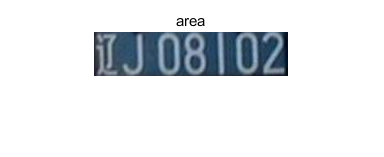

imshow(img_area);title("area");

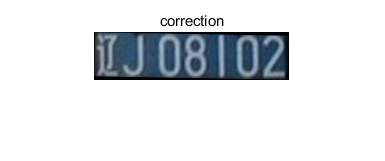


img_correction = correction(img_area);
imshow(img_correction);title("correction");

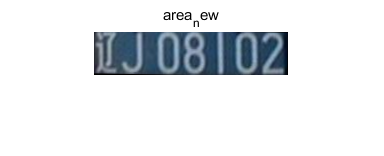


img_area_new = accurate_select(img_correction,color);
imshow(img_area_new);title("area_new");

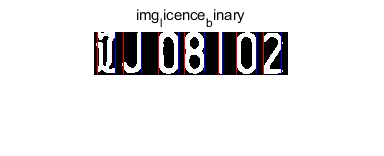


[img_final,result_list,number_list,img_reshaped_list] = segmentation(img_area_new);

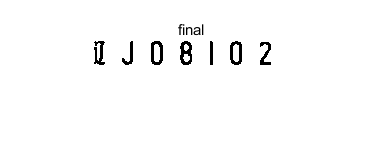


imshow(img_final);title("final");

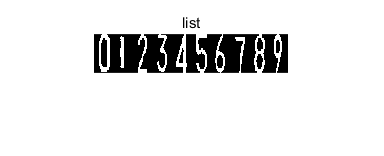

imshow(number_list*255);title("list");

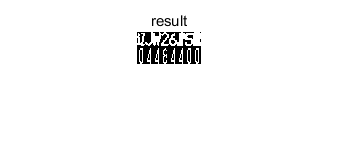

imshow(img_reshaped_list*255);title("result");


result_list

result_list =      0     0     0     0     0     0     2
